***Bureau d'étude Sous Marin***

clear all
close all
clc

## Introduction

Ce bureau d'étude à pour objectif d'étudier....

# **Partie I : Modélisation du système**

% Define matrix values for 6 knots
a11_6 = -0.038006;
a12_6 = 0.89604;
a14_6 = 0.0014673;
a21_6 = 0.0017105;
a22_6 = -0.091676;
a24_6 = -0.0056095;
a34_6 = -3.0867;
b11_6 = -0.007542;
b12_6 = -0.022859;
b21_6 = 0.0017323;
b22_6 = -0.0022217;

% Define matrices A, B, C, and D for 6 knots
A_6knots = [a11_6, a12_6, 0, a14_6;
            a21_6, a22_6, 0, a24_6;
            1, 0, 0, a34_6;
            0, 1, 0, 0];

B_6knots = [b11_6, b12_6;
            b21_6, b22_6;
            0, 0;
            0, 0];

C_6knots = [0, 0, 1, 0;
            0, 0, 0, 1];

D_6knots = 0;

% Define matrix values for 30 knots
a11_30 = -0.19003;
a12_30 = 4.4802;
a14_30 = 0.0014673;
a21_30 = 0.0085526;
a22_30 = -0.45988;
a24_30 = -0.0056095;
a34_30 = -15.433;
b11_30 = -0.1855;
b12_30 = -0.57149;
b21_30 = 0.043308;
b22_30 = -0.055543;

% Define matrices A, B, C, and D for 30 knots
A_30knots = [a11_30, a12_30, 0, a14_30;
             a21_30, a22_30, 0, a24_30;
             1, 0, 0, a34_30;
             0, 1, 0, 0];

B_30knots = [b11_30, b12_30;
             b21_30, b22_30;
             0, 0;
             0, 0];

C_30knots = [0, 0, 1, 0;
             0, 0, 0, 1];

D_30knots = 0;


# **Partie II : Analyse des caractéristiques du système**

Pour l'analyse du système, nous considérons le cas 6knots puis le cas 30knots. Cette disjonction permettra une meilleure clarté des explications. 

## Etude pour 6 knots :

- **Modèle du système sous forme d'espace d'état**

sys_6knots = ss(A_6knots, B_6knots, C_6knots, D_6knots);
sys_30knots = ss(A_30knots, B_30knots, C_30knots, D_30knots);

[Vecp_6,Valp_6]=eig(A_6knots);
[Vecp_30,Valp_30]=eig(A_30knots);

Nous récuperons la valeur des valeurs et vecteurs propres, pour les différents noeuds. 

***        2. ******Etude de l'observabilité et de la commandabilité:***

L'observabilité et la commandabilité du système s'étudie via l'analyse de l'espace image des matrices Qo et Gc. Nous allons donc nous intéresser au rang de ces 2 matrices. Nous Etudierons ces 2 propriétés pour les deux valeurs de vitesse.

observabl_controlable(sys_6knots, A_6knots, 6);

Le rang de la matrice contrôlable pour 6 knots est : 4
Le rang de la matrice observable pour 6 knots est : 4
Le système pour 6 knots est observable et contrôlable.


stabilite_syst(A_6knots);

Nous ne pouvons pas déterminer la stabilité du système, car il possède 1 valeur(s) propre(s) nulle(s).
Le système possède 3 valeur(s) propre(s) négative(s).
                                                                        
         Pole              Damping       Frequency       Time Constant  
                                       (rad/TimeUnit)     (TimeUnit)    
                                                                        
  0.00e+00                -1.00e+00       0.00e+00               Inf    
 -3.35e-02 + 4.73e-02i     5.78e-01       5.80e-02          2.98e+01    
 -3.35e-02 - 4.73e-02i     5.78e-01       5.80e-02          2.98e+01    
 -6.27e-02                 1.00e+00       6.27e-02          1.60e+01    


Q3) on a un pole en 0 qui a un damping de -1 --> même a une instabilité on a des poles complexes conjugés ds le demi plan gauche ils on un damping faible donc faiblement amortie et vont osciller jusqu'à converger. Limite de stabilité (cv vers une valeurs différentes de 0) stable asymptotiquement pour l'angles c'est stable et le zero n'influence pas la stabilité de l'angle. 

***        3. ******Observation des pôles :***

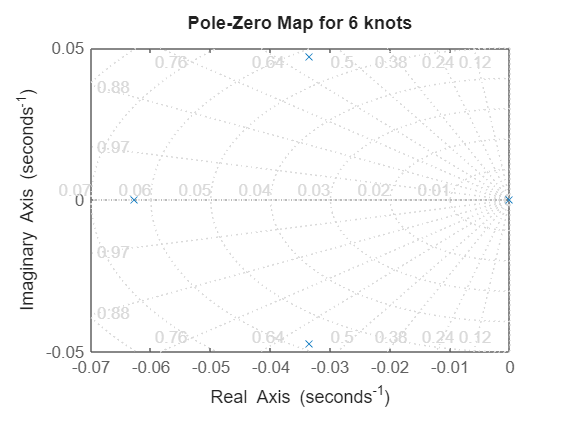

% Plot pole-zero maps for both systems
figure;
pzmap(sys_6knots);
title('Pole-Zero Map for 6 knots');
grid minor;

***        4. ******Visualisation des réponses indicielles du système :***

% Convert to transfer function and plot
FBO_6 = tf(sys_6knots);
fprintf('La fonction de transfert du système 6 knots :\n');

La fonction de transfert du système 6 knots :


FBO_6


FBO_6 =
 
  From input 1 to output...
          -0.007542 s^2 - 0.004486 s - 0.0002032
   1:  ---------------------------------------------
       s^4 + 0.1297 s^3 + 0.007561 s^2 + 0.0002107 s
 
                0.001732 s + 5.294e-05
   2:  -----------------------------------------
       s^3 + 0.1297 s^2 + 0.007561 s + 0.0002107
 
  From input 2 to output...
           -0.02286 s^2 + 0.002771 s + 0.0002498
   1:  ---------------------------------------------
       s^4 + 0.1297 s^3 + 0.007561 s^2 + 0.0002107 s
 
                -0.002222 s - 0.0001235
   2:  -----------------------------------------
       s^3 + 0.1297 s^2 + 0.007561 s + 0.0002107
 
Continuous-time transfer function.


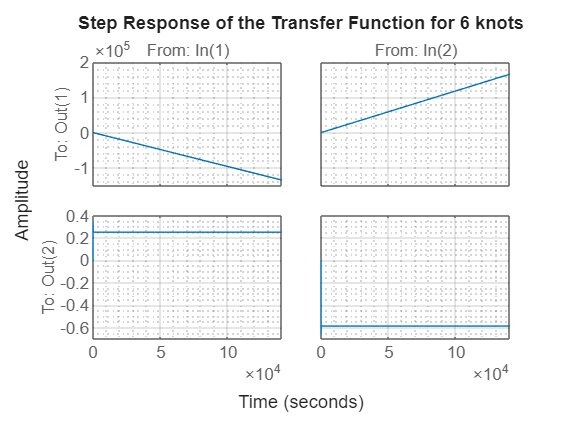

%% Alternatively, you can use step response
figure;
stepplot(FBO_6);
title('Step Response of the Transfer Function for 6 knots');
grid minor;

Nous observons :

Les deux courbes du haut montrent que la position du sous-marin a un comportement linéaire car nous appliquons une tension en échelon. Les deux courbes du bas montrent que l''angle du sous-marin est constant, car la position est linéaire

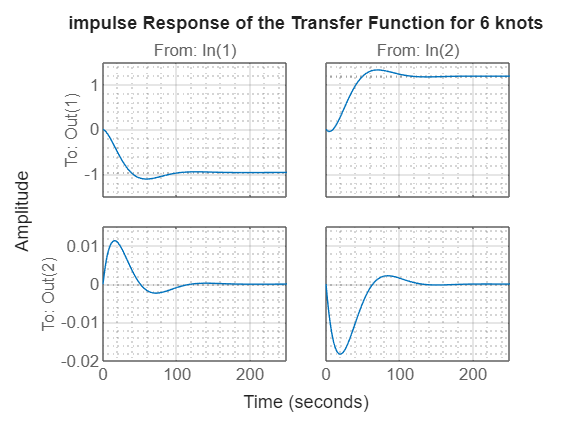

% Alternatively, you can use impulse response
figure;
impulse(FBO_6);
title('impulse Response of the Transfer Function for 6 knots');
grid minor;

Nous observons :

Les deux courbes du haut montrent que la position du sous-marin suit un comportement en échelon, car nous appliquons une tension en impulsion. Les deux courbes du bas montrent que l''angle du sous-marin oscille au début, puis tend vers 0. Cela s''explique par le fait que, une fois que le sous-marin atteint son niveau de mer souhaité, il se remet à plat.

- ***Mise en avant d'un couplage***

## Etude pour 30 knots :

- **Modèle du système sous forme d'espace d'état**

***        2. ******Etude de l'observabilité et de la commandabilité:***


observabl_controlable(sys_30knots, A_30knots, 30);

Le rang de la matrice contrôlable pour 30 knots est : 4
Le rang de la matrice observable pour 30 knots est : 4
Le système pour 30 knots est observable et contrôlable.



fprintf('répondre la question 3\n');

répondre la question 3



stabilite_syst(A_30knots);

Nous ne pouvons pas déterminer la stabilité du système, car il possède 1 valeur(s) propre(s) nulle(s).
Le système possède 3 valeur(s) propre(s) négative(s).
                                                            
   Pole        Damping       Frequency       Time Constant  
                           (rad/TimeUnit)     (TimeUnit)    
                                                            
  0.00e+00    -1.00e+00       0.00e+00               Inf    
 -5.55e-01     1.00e+00       5.55e-01          1.80e+00    
 -6.67e-02     1.00e+00       6.67e-02          1.50e+01    
 -2.85e-02     1.00e+00       2.85e-02          3.51e+01    


***         3. ******Observation des pôles :***

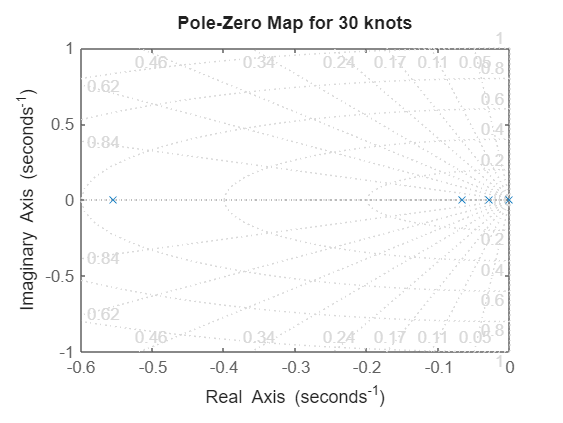

% Plot pole-zero maps for both systems
figure;
pzmap(sys_30knots);
title('Pole-Zero Map for 30 knots');
grid minor;

***        4. ******Visualisation des réponses indicielles du système :***

% Convert to transfer function and plot
FBO_30 = tf(sys_30knots);
fprintf('La fonction de transfert du système 30 knots:\n');

La fonction de transfert du système 30 knots:


FBO_30


FBO_30 =
 
  From input 1 to output...
             -0.1855 s^2 - 0.5597 s - 0.1035
   1:  -------------------------------------------
       s^4 + 0.6499 s^3 + 0.05468 s^2 + 0.001053 s
 
                0.04331 s + 0.006643
   2:  ---------------------------------------
       s^3 + 0.6499 s^2 + 0.05468 s + 0.001053
 
  From input 2 to output...
             -0.5715 s^2 + 0.3455 s + 0.235
   1:  -------------------------------------------
       s^4 + 0.6499 s^3 + 0.05468 s^2 + 0.001053 s
 
                -0.05554 s - 0.01544
   2:  ---------------------------------------
       s^3 + 0.6499 s^2 + 0.05468 s + 0.001053
 
Continuous-time transfer function.


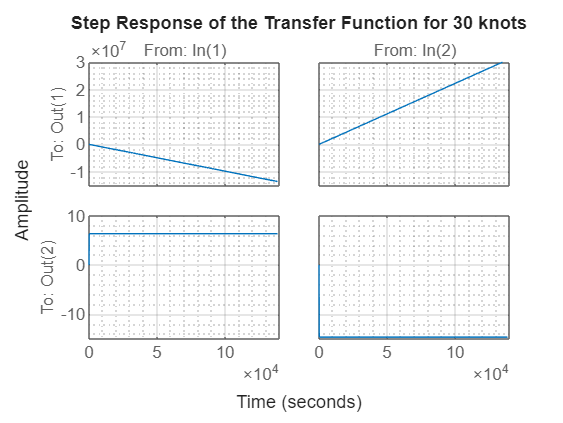


% Alternatively, you can use step response
figure;
stepplot(FBO_30);
title('Step Response of the Transfer Function for 30 knots');
grid minor;

Nous observons :

Les deux courbes du haut montrent que la position du sous-marin a un comportement linéaire car nous appliquons une tension en échelon. Les deux courbes du bas montrent que l''angle du sous-marin est constant, car la position est linéaire

fprintf('répondre la question 5\n');

répondre la question 5


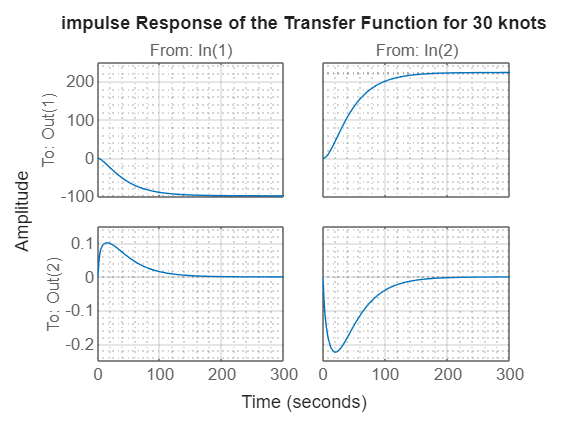

% Alternatively, you can use step response
figure;
impulse(FBO_30);
title('impulse Response of the Transfer Function for 30 knots');
grid minor;

Nous observons :

Les deux courbes du haut montrent que la position du sous-marin suit un comportement en échelon, car nous appliquons une tension en impulsion. Les deux courbes du bas montrent que l''angle du sous-marin oscille au début, puis tend vers 0. Cela s''explique par le fait que, une fois que le sous-marin atteint son niveau de mer souhaité, il se remet à plat.

# **Partie IV : Réalisation des objectifs**

- **Justification des valeurs propres**

Notre fonction de transfert est un ordre 4 (deux ordre 2). Il donc possible sous certaines conditions, d'approximer cet ordre 4 par deux fonctions de transfert d'ordre 1. Donc pour chaque ordre 2, il est nécessaire de négliger la dynamique d'un pole. L'autre pôle, est obtenue avec la relation classique : tr = 3tau.  

M=1;
lambda1=-3/100;
lambda2=-3/80;
Lambda=[lambda1, lambda1*10, lambda2, lambda2*10 ];
V=[0, 0, 1 ,2 ; 1, 2, 0, 0];

# **Partie V : Choix de la dynamique et découplage**

Dans cette partie, nous allons nous intéresser à la méthode permettant d'imposer une dynamique souhaitée ainsi que d'établir un découplage entre variables d'états et consignes.

- Dimension et forme de la matrice de découplage

Nous cherchons à découpler l'influence des entrées avec les variables d'états. Pour cela, nous imposons :

CV = [0,0,*,*; *, *, 0,0];

V = [*,*,*,*; *,*,*,*; *, *, 0,0];

CVv = [0,0,'*','*';'*','*',0,0];
Vv =[ '*', '*', '*', '*';
 '*', '*', '*', '*';
 '*', '*', 0, 0; 
 0,0, '*', '*'];


## Etude pour 6 knots :

**        2. ****Dynamique en boucle fermé**

L'objectif de cette partie est de déterminer la valeur de K permettant d'imposer une dynamique souhaitée pour le système en placant les pôles de manière désirées. Cette détermination nécessite la connaissance d'une matrice V, tel que K=Z*inv(V).

Calcul de la dynamique en boucle fermé

%% 6knots
[Vresult_6,K_6,H_6] = calcul_K_H(A_6knots, B_6knots, C_6knots, M,V, Lambda);

H_cor_6=Hcorriger(H_6,-1.8,0.27);

A_cor_6knots=A_6knots-B_6knots*K_6;
B_cor_6knots=B_6knots*H_cor_6;
C_cor_6knots=C_6knots;
D_cor_6knots=D_6knots;

sys_cor_6knots = ss(A_cor_6knots, B_cor_6knots, C_cor_6knots, D_cor_6knots);


Q1) Matrice V est 2x4 V = [*,*,0,0; 0,0,*,*] Comme ça la consigne y1 ne gère que les modes 1 et 2 et la commande y2 que modes 3 et 4. 

Q2) une fois qu'on a V il y a plsuioeurs choix : - soit on choisir valeur pour les * arbitrairement piur V en respectant condition que V inversible car on voudra calculer V-1. - Optimiser le choix des vecteurs propres a partirs des libre non entierement spécifiées (recherche meilleur vp) on travail avec v~  voir photo. Et on verifie que toutes matrices ont la bonne forme

**        3. ****Détermination de la matrice H**

Nous souhaitons déterminer la forme de la matrice H qui permet un découplage à gauche de notre système. Pour ce faire, nous partons de la dimension de cette matrice. Pour respecter les contraines de dimension, cette matrice doit être de dimension 2x2. Nous posons alors :

H = [h11, h12; h21, h22];

Sachant ceci, nous 

stabilite_syst(A_cor_6knots);

Le système est stable et toutes les valeurs propres sont négatives.
                                                            
   Pole        Damping       Frequency       Time Constant  
                           (rad/TimeUnit)     (TimeUnit)    
                                                            
 -3.75e-01     1.00e+00       3.75e-01          2.67e+00    
 -3.75e-02     1.00e+00       3.75e-02          2.67e+01    
 -3.00e-01     1.00e+00       3.00e-01          3.33e+00    
 -3.00e-02     1.00e+00       3.00e-02          3.33e+01    


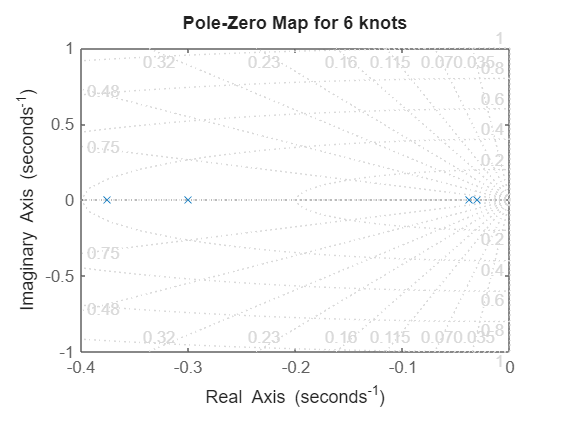

figure;
pzmap(sys_cor_6knots);
title('Pole-Zero Map for 6 knots');
grid minor;


% Convert to transfer function and plot
FBO_cor_6 = tf(sys_cor_6knots);
fprintf('La fonction de transfert du système 6 knots :\n');

La fonction de transfert du système 6 knots :


FBO_cor_6


FBO_cor_6 =
 
  From input 1 to output...
                0.01409 s^2 + 0.00465 s + 0.0001268
   1:  ------------------------------------------------------
       s^4 + 0.7425 s^3 + 0.1592 s^2 + 0.008353 s + 0.0001266
 
              -2.168e-19 s^2 - 1.204e-19 s - 1.952e-21
   2:  ------------------------------------------------------
       s^4 + 0.7425 s^3 + 0.1592 s^2 + 0.008353 s + 0.0001266
 
  From input 2 to output...
              1.298e-16 s^2 + 1.386e-17 s + 1.834e-18
   1:  ------------------------------------------------------
       s^4 + 0.7425 s^3 + 0.1592 s^2 + 0.008353 s + 0.0001266
 
               0.009131 s^2 + 0.003766 s + 0.0001284
   2:  ------------------------------------------------------
       s^4 + 0.7425 s^3 + 0.1592 s^2 + 0.008353 s + 0.0001266
 
Continuous-time transfer function.


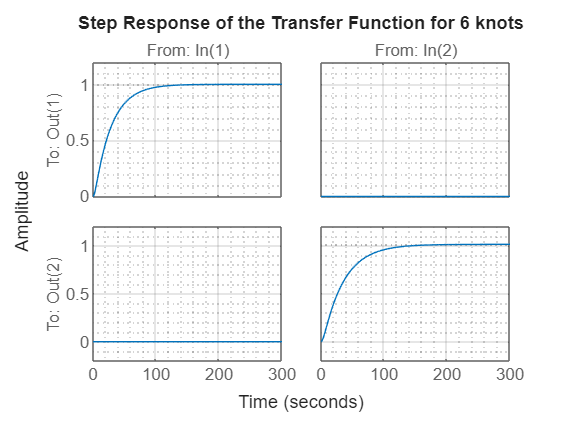


%% Alternatively, you can use step response
figure;
stepplot(FBO_cor_6);
title('Step Response of the Transfer Function for 6 knots');
grid minor;

## Etude pour 30 knots :

%% 30knots
[Vresult_30,K_30,H_30] = calcul_K_H(A_30knots, B_30knots, C_30knots, M,V, Lambda);
H_cor_30=Hcorriger(H_30,-45,6.8);

A_cor_30knots=A_30knots-B_30knots*K_30;
B_cor_30knots=B_30knots*H_cor_30;
C_cor_30knots=C_30knots;
D_cor_30knots=D_30knots;

sys_cor_30knots = ss(A_cor_30knots, B_cor_30knots, C_cor_30knots, D_cor_30knots);


stabilite_syst(A_cor_30knots);

Le système est stable et toutes les valeurs propres sont négatives.
                                                            
   Pole        Damping       Frequency       Time Constant  
                           (rad/TimeUnit)     (TimeUnit)    
                                                            
 -3.75e-01     1.00e+00       3.75e-01          2.67e+00    
 -3.75e-02     1.00e+00       3.75e-02          2.67e+01    
 -3.00e-02     1.00e+00       3.00e-02          3.33e+01    
 -3.00e-01     1.00e+00       3.00e-01          3.33e+00    


figure;
pzmap(sys_cor_30knots);
title('Pole-Zero Map for 6 knots');
grid minor;

% Convert to transfer function and plot
FBO_cor_30 = tf(sys_cor_30knots);
fprintf('La fonction de transfert du système 6 knots :\n');

La fonction de transfert du système 6 knots :


FBO_cor_30


FBO_cor_30 =
 
  From input 1 to output...
                0.01402 s^2 + 0.004628 s + 0.0001262
   1:  ------------------------------------------------------
       s^4 + 0.7425 s^3 + 0.1592 s^2 + 0.008353 s + 0.0001266
 
              5.459e-16 s^2 + 2.211e-16 s + 6.142e-18
   2:  ------------------------------------------------------
       s^4 + 0.7425 s^3 + 0.1592 s^2 + 0.008353 s + 0.0001266
 
  From input 2 to output...
              -1.907e-10 s^2 - 1.287e-10 s - 2.145e-11
   1:  ------------------------------------------------------
       s^4 + 0.7425 s^3 + 0.1592 s^2 + 0.008353 s + 0.0001266
 
                0.00902 s^2 + 0.003721 s + 0.0001268
   2:  ------------------------------------------------------
       s^4 + 0.7425 s^3 + 0.1592 s^2 + 0.008353 s + 0.0001266
 
Continuous-time transfer function.


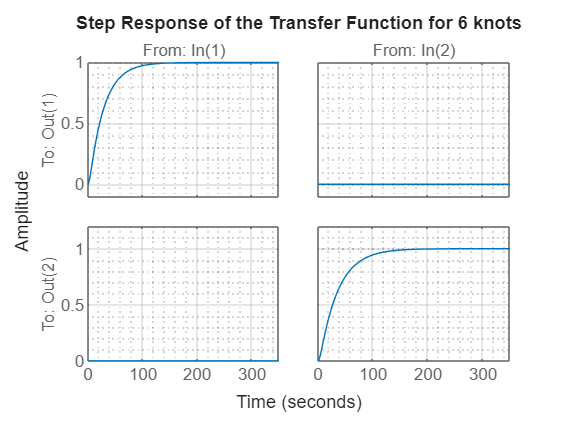


%% Alternatively, you can use step response
figure;
stepplot(FBO_cor_30);
title('Step Response of the Transfer Function for 6 knots');
grid minor;

# **Partie VI : Découplage en mode statique**

L'objectif de cette partie est de déterminer la valeur de.

%% 6knots
H_st_6=Hstatic(A_6knots,B_6knots,C_6knots,K_6);
B_st_6knots=B_6knots*H_st_6;

sys_st_6knots = ss(A_cor_6knots, B_st_6knots, C_cor_6knots, D_cor_6knots);

%% 30knots
H_st_30=Hstatic(A_30knots,B_30knots,C_30knots,K_30);
B_st_30knots=B_30knots*H_st_30;
sys_st_30knots = ss(A_cor_30knots, B_st_30knots, C_cor_30knots, D_cor_30knots);


***Etude du système pour 6 knots***

% Convert to transfer function and plot
FBO_st_6 = tf(sys_st_6knots);
fprintf('La fonction de transfert du système 6 knots :\n');

La fonction de transfert du système 6 knots :


FBO_st_6


FBO_st_6 =
 
  From input 1 to output...
                0.01406 s^2 + 0.004641 s + 0.0001266
   1:  ------------------------------------------------------
       s^4 + 0.7425 s^3 + 0.1592 s^2 + 0.008353 s + 0.0001266
 
                      -4.879e-20 s - 3.591e-36
   2:  ------------------------------------------------------
       s^4 + 0.7425 s^3 + 0.1592 s^2 + 0.008353 s + 0.0001266
 
  From input 2 to output...
               3.837e-16 s^2 + 1.22e-16 s + 3.629e-18
   1:  ------------------------------------------------------
       s^4 + 0.7425 s^3 + 0.1592 s^2 + 0.008353 s + 0.0001266
 
                 0.009 s^2 + 0.003713 s + 0.0001266
   2:  ------------------------------------------------------
       s^4 + 0.7425 s^3 + 0.1592 s^2 + 0.008353 s + 0.0001266
 
Continuous-time transfer function.


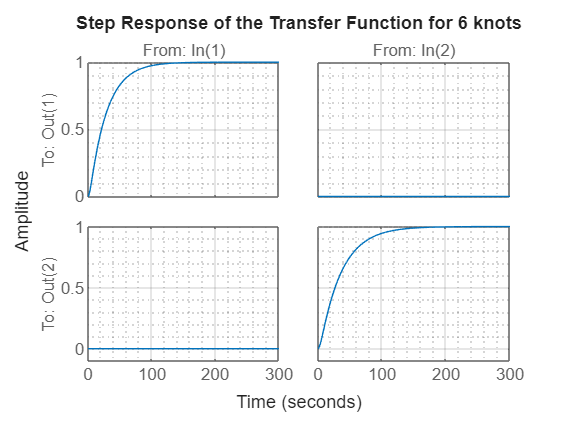


%% Alternatively, you can use step response
figure;
stepplot(FBO_st_6);
title('Step Response of the Transfer Function for 6 knots');
grid minor;

***Etude du système pour 30 knots***

% Convert to transfer function and plot
FBO_st_30 = tf(sys_st_30knots);
fprintf('La fonction de transfert du système 30 knots :\n');

La fonction de transfert du système 30 knots :


FBO_st_30


FBO_st_30 =
 
  From input 1 to output...
                0.01406 s^2 + 0.004641 s + 0.0001266
   1:  ------------------------------------------------------
       s^4 + 0.7425 s^3 + 0.1592 s^2 + 0.008353 s + 0.0001266
 
              1.093e-16 s^2 + 4.098e-17 s - 1.342e-21
   2:  ------------------------------------------------------
       s^4 + 0.7425 s^3 + 0.1592 s^2 + 0.008353 s + 0.0001266
 
  From input 2 to output...
              2.188e-09 s^2 + 6.564e-10 s + 1.876e-17
   1:  ------------------------------------------------------
       s^4 + 0.7425 s^3 + 0.1592 s^2 + 0.008353 s + 0.0001266
 
                 0.009 s^2 + 0.003713 s + 0.0001266
   2:  ------------------------------------------------------
       s^4 + 0.7425 s^3 + 0.1592 s^2 + 0.008353 s + 0.0001266
 
Continuous-time transfer function.


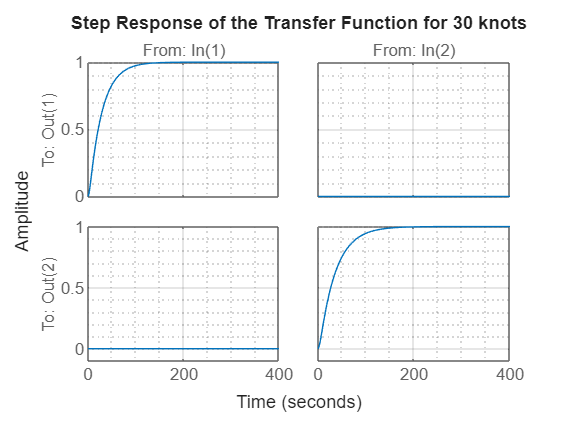


%% Alternatively, you can use step response
figure;
stepplot(FBO_st_30);
title('Step Response of the Transfer Function for 30 knots');
grid minor;

***        3. ******Découplage satisfait du système***

Enfin dans cette dernière sous partie, nous allons vérifier que le découplage est correctement réalisé. Nous remarquons que le système est correctement découplé dans la mesure ou la consigne yc2 n'infleunce plus le comportement de la 1ère variable d'état, et inversement.

# **Partie VII : Placement pôle insensible**

- **Etude de la fonction place.m**

Pour ce faire, nous allons utiliser la fonction place, qui permet de placer les pôles en boucle fermé via un retour d'état. Pour ce faire, la fonction va calculer une matrice K, de telles manière que la matrice A-B*K possède les mêmes valeurs propres que celles souhaitées pour imposer la dynamique.

        2. **Implémentation du retour d'état **

Nous allons mettre en place la méthode de placement de pôle tout en minimisant la sensibilité du système. Nous allons donc utiliser la fonction place, qui en plus de calculer la velur de K permet de minimiser la sensibilité des pôles.


%% 6knots
K_place_6=place(A_6knots,B_6knots,Lambda);

A_place_6knots=A_6knots-B_6knots*K_place_6;

sys_place_6knots = ss(A_place_6knots, B_st_6knots, C_cor_6knots, D_cor_6knots);


%% 30knots
K_place_30=place(A_30knots,B_30knots,Lambda);

A_place_30knots=A_30knots-B_30knots*K_place_30;

sys_place_30knots = ss(A_place_30knots, B_st_30knots, C_cor_30knots, D_cor_30knots);


***Etude du système pour 6 knots***

% Convert to transfer function and plot
FBO_place_6 = tf(sys_place_6knots);
fprintf('La fonction de transfert du système 6 knots :\n');

La fonction de transfert du système 6 knots :


FBO_place_6


FBO_place_6 =
 
  From input 1 to output...
                0.01406 s^2 + 0.004784 s + 0.0001311
   1:  ------------------------------------------------------
       s^4 + 0.7425 s^3 + 0.1592 s^2 + 0.008353 s + 0.0001266
 
                      -0.0001725 s - 7.086e-06
   2:  ------------------------------------------------------
       s^4 + 0.7425 s^3 + 0.1592 s^2 + 0.008353 s + 0.0001266
 
  From input 2 to output...
                      -0.0004979 s - 1.736e-05
   1:  ------------------------------------------------------
       s^4 + 0.7425 s^3 + 0.1592 s^2 + 0.008353 s + 0.0001266
 
                 0.009 s^2 + 0.003621 s + 0.0001231
   2:  ------------------------------------------------------
       s^4 + 0.7425 s^3 + 0.1592 s^2 + 0.008353 s + 0.0001266
 
Continuous-time transfer function.


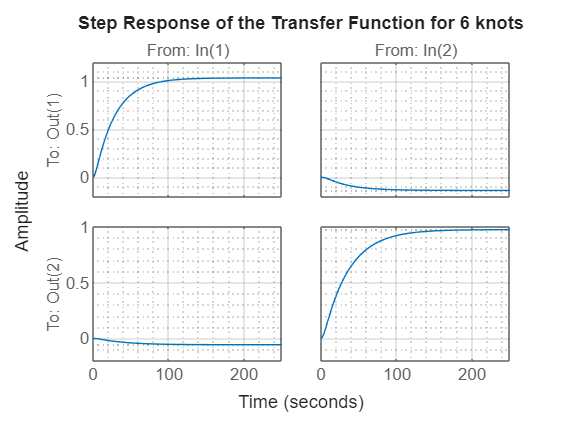

%% Alternatively, you can use step response
figure;
stepplot(FBO_place_6);
title('Step Response of the Transfer Function for 6 knots');
grid minor;

***Etude du système pour 30 knots***


% Convert to transfer function and plot
FBO_place_30 = tf(sys_place_30knots);
fprintf('La fonction de transfert du système 30 knots :\n');

La fonction de transfert du système 30 knots :


FBO_place_30


FBO_place_30 =
 
  From input 1 to output...
                0.01406 s^2 + 0.00485 s + 0.0001331
   1:  ------------------------------------------------------
       s^4 + 0.7425 s^3 + 0.1592 s^2 + 0.008353 s + 0.0001266
 
              1.093e-16 s^2 - 3.903e-05 s - 1.616e-06
   2:  ------------------------------------------------------
       s^4 + 0.7425 s^3 + 0.1592 s^2 + 0.008353 s + 0.0001266
 
  From input 2 to output...
               2.188e-09 s^2 - 0.002982 s - 0.0001041
   1:  ------------------------------------------------------
       s^4 + 0.7425 s^3 + 0.1592 s^2 + 0.008353 s + 0.0001266
 
                 0.009 s^2 + 0.003579 s + 0.0001216
   2:  ------------------------------------------------------
       s^4 + 0.7425 s^3 + 0.1592 s^2 + 0.008353 s + 0.0001266
 
Continuous-time transfer function.


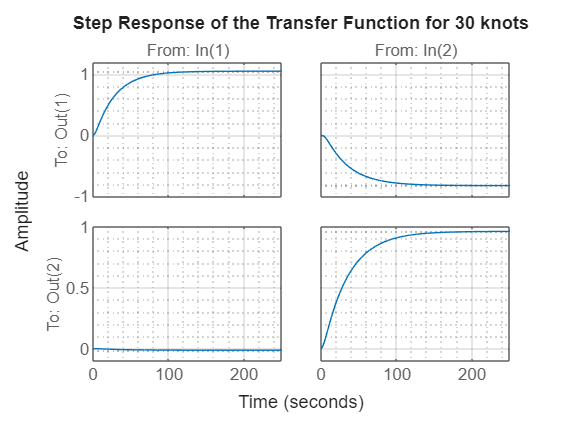

%% Alternatively, you can use step response
figure;
stepplot(FBO_place_30);
title('Step Response of the Transfer Function for 30 knots');
grid minor;

        3. **Contraintes de découplage**

On remarque que notre système présente des phénomènes de couplage, yc2 a une influence sur la dynamique de la 1ère variable d'état. Ceci est tout à fait normal, dans la mesure ou notre étude a été mené sur l'insensibilité des pôles et non sur le découplage. Il y a un compromis à trouver entre insensibilité et découplage.

Comme nous utilisons la matrice H dans le système, nous remarquons bien un decouplge dans le graphe en bas a gauche.

# **Parti VIII : Etude de sensibilité**

Dans cette partie nous allons regarder la sensibilité de notre système vis à vis des pôles 

- **Etude de la fonction cond.m**

        2.  **Etude des la sensibilité pour le placement de pôles choisi**

[Vecp_cor_6, Valp_cor_6]=eig(A_cor_6knots);

[Vecp_cor_30, Valp_cor_30]=eig(A_cor_30knots);

[Vecp_place_6, Valp_place_6]=eig(A_place_6knots);

[Vecp_place_30, Valp_place_30]=eig(A_place_30knots);



*Sensibilité de la boucle ouvert *

Pour 6knots

cond(Vecp_6)

ans = 1.5307e+03

Pour 30knots

cond(Vecp_30)

ans = 1.1336e+04

*Sensibilité de la boucle fermet *

Pour 6knots

cond(Vecp_cor_6)

ans = 27.1246

Pour 30knots

cond(Vecp_cor_30)

ans = 129.9299

*Sensibilité de la boucle mode placement de pole*

Pour 6knots

cond(Vecp_place_6)

ans = 28.1878

Pour 30knots

cond(Vecp_place_30)

ans = 136.0546

U1=0


%% 6knots
K_U2_6=place(A_6knots,B_6knots(:,2),Lambda);

A_U2_6knots=A_6knots-B_6knots(:,2)*K_U2_6;

sys_U2_6knots = ss(A_U2_6knots, B_st_6knots(:,2), C_cor_6knots(2,:), D_cor_6knots);


%% 30knots
K_U2_30=place(A_30knots,B_30knots(:,2),Lambda);

A_U2_30knots=A_30knots-B_30knots(:,2)*K_U2_30;

sys_U2_30knots = ss(A_U2_30knots, B_st_30knots(:,2), C_cor_30knots(2,:), D_cor_30knots);




U2=0


%% 6knots
K_U1_6=place(A_6knots,B_6knots(:,1),Lambda);

A_U1_6knots=A_6knots-B_6knots(:,1)*K_U2_6;

sys_U1_6knots = ss(A_U2_6knots, B_st_6knots(:,1), C_cor_6knots(1,:), D_cor_6knots);


%% 30knots
K_U1_30=place(A_30knots,B_30knots(:,1),Lambda);

A_U1_30knots=A_30knots-B_30knots(:,1)*K_U1_30;

sys_U1_30knots = ss(A_U1_30knots, B_st_30knots(:,1), C_cor_30knots(1,:), D_cor_30knots);

***Etude du système pour 6 knots***

% Convert to transfer function and plot
FBO_U2_6 = tf(sys_U2_6knots);
fprintf('La fonction de transfert du système 6 knots :\n');

La fonction de transfert du système 6 knots :


FBO_U2_6


FBO_U2_6 =
 
            0.009 s^2 + 0.00397 s - 0.0001042
  ------------------------------------------------------
  s^4 + 0.7425 s^3 + 0.1592 s^2 + 0.008353 s + 0.0001266
 
Continuous-time transfer function.
Model Properties


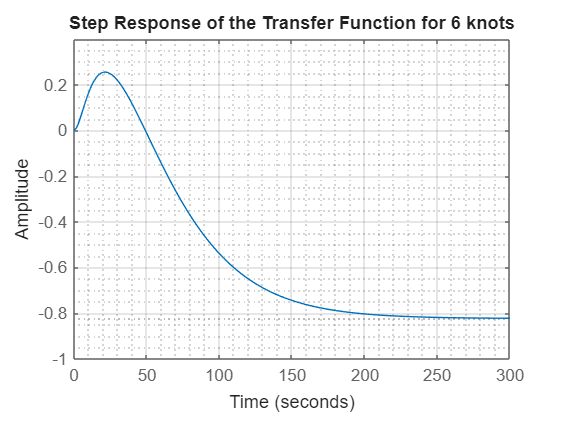

%% Alternatively, you can use step response
figure;
stepplot(FBO_U2_6);
title('Step Response of the Transfer Function for 6 knots');
grid minor;


% Convert to transfer function and plot
FBO_U1_6 = tf(sys_U1_6knots);
fprintf('La fonction de transfert du système 6 knots :\n');

La fonction de transfert du système 6 knots :


FBO_U1_6


FBO_U1_6 =
 
           0.01406 s^2 + 0.004239 s + 0.002823
  ------------------------------------------------------
  s^4 + 0.7425 s^3 + 0.1592 s^2 + 0.008353 s + 0.0001266
 
Continuous-time transfer function.
Model Properties


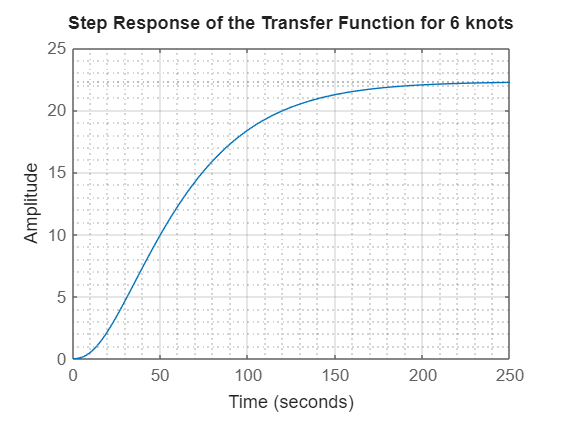

%% Alternatively, you can use step response
figure;
stepplot(FBO_U1_6);
title('Step Response of the Transfer Function for 6 knots');
grid minor;

***Etude du système pour 30 knots***


% Convert to transfer function and plot
FBO_U2_30 = tf(sys_U2_30knots);
fprintf('La fonction de transfert du système 30 knots :\n');

La fonction de transfert du système 30 knots :


FBO_U2_30


FBO_U2_30 =
 
            0.009 s^2 + 0.002517 s - 2.77e-06
  ------------------------------------------------------
  s^4 + 0.7425 s^3 + 0.1592 s^2 + 0.008353 s + 0.0001266
 
Continuous-time transfer function.
Model Properties


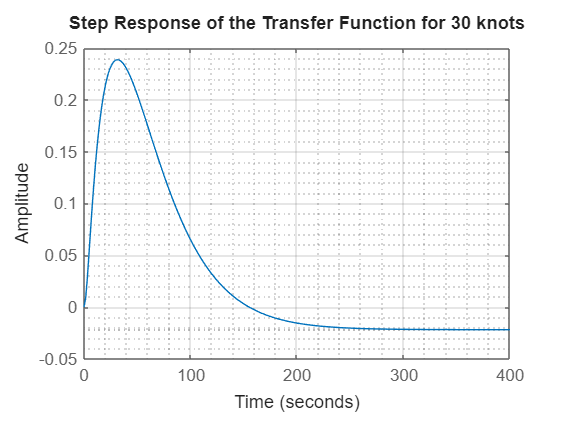

%% Alternatively, you can use step response
figure;
stepplot(FBO_U2_30);
title('Step Response of the Transfer Function for 30 knots');
grid minor;


% Convert to transfer function and plot
FBO_U1_30 = tf(sys_U1_30knots);
fprintf('La fonction de transfert du système 30 knots :\n');

La fonction de transfert du système 30 knots :


FBO_U1_30


FBO_U1_30 =
 
           0.01406 s^2 + 0.008622 s + 0.001933
  ------------------------------------------------------
  s^4 + 0.7425 s^3 + 0.1592 s^2 + 0.008353 s + 0.0001266
 
Continuous-time transfer function.
Model Properties


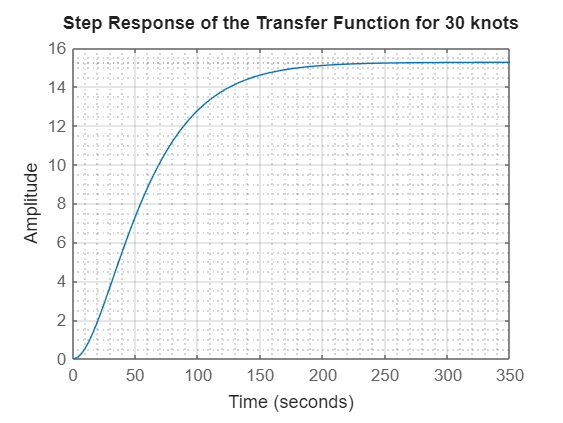

%% Alternatively, you can use step response
figure;
stepplot(FBO_U1_30);
title('Step Response of the Transfer Function for 30 knots');
grid minor;

# **Parti IX : Conclusion**